# 连续系统&离散系统转换

## 传递函数

xi = 0.5;
omega = 10^3.5;
G=tf([1 0 omega^2],[1 2*xi*omega omega^2])

G =
 
      s^2 + 1e07
  -------------------
  s^2 + 3162 s + 1e07
 
连续时间传递函数。
模型属性


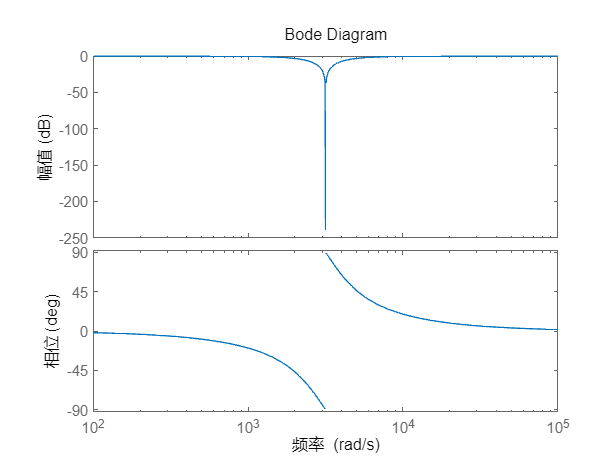

bode(G);

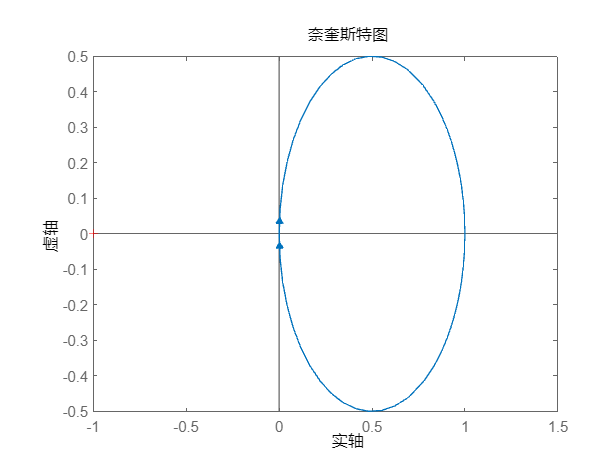

nyquist(G);

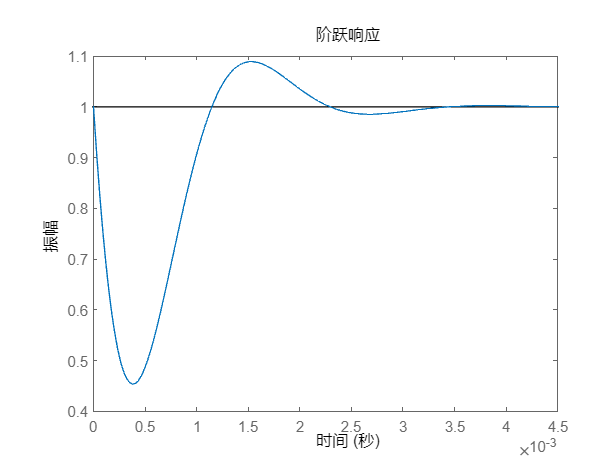

step(G);

## 转换为离散系统

Z=c2d(G,1/20e3,'foh')

Z =
 
  0.9251 z^2 - 1.827 z + 0.9248
  -----------------------------
     z^2 - 1.831 z + 0.8538
 
采样时间: 5e-05 seconds
离散时间传递函数。
模型属性


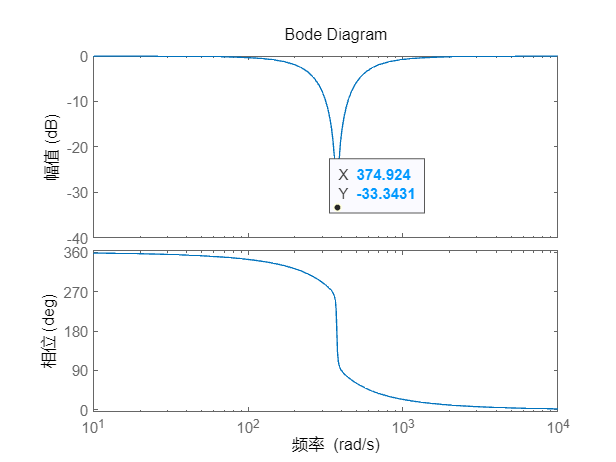

tz = tf([1 -2 1.000346],[1 -1.9814 0.981746],0.00005);
Gs = d2c(tz);
bode(Gs)